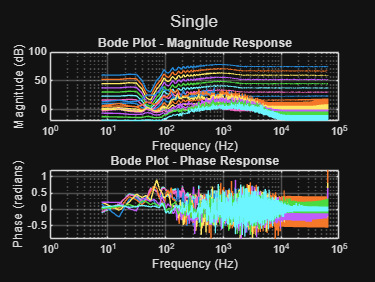

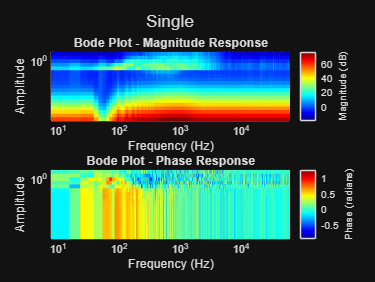

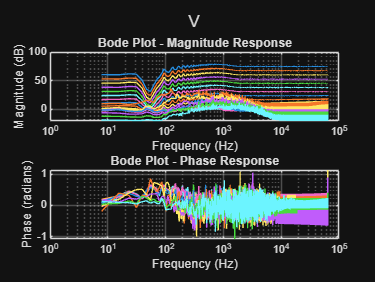

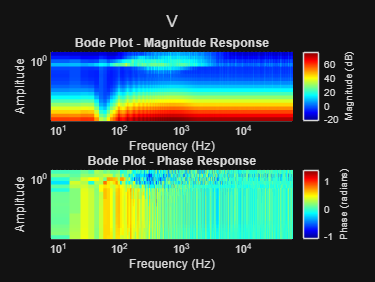

fs = 128e+3;
tmax = 2;

h = 1/fs;
%
f0 = 5e+1;
f1 = 5e+2;
A = 1;

k = 5; % Number of cycles
N = ceil(k * fs / f0);
N_fft = 2^nextpow2(N);

% Define FFT options
fft_opts.window = kaiser(N, 2.5);
fft_opts.nfft = N_fft;
fft_opts.noverlap = round(N / 2);
fft_opts.sides = 'onesided';

A_range = logspace(-6, 1, 20);

% Magnitude response
mr = zeros(N_fft/2+1, numel(A_range));
% Phase response
pr = zeros(N_fft/2+1, numel(A_range));

modelNames = {'Single', 'V', 'L', 'VV', 'LV', 'VVV'};
treeModels = getModels();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Initialize storage for sigma and mu
numModels = numel(treeModels);

for modelIdx = 1 : 2 % numModels
    for ai = 1: numel(A_range)
        A = A_range(ai);
        [~, sig] = Chirp(A, tmax, fs, f0, f1, signal="sin", type="log");
        switch modelIdx
            case 1 % Single
                treeModels{modelIdx}.addStimuli(0, sig);
            case 2 % V
                treeModels{modelIdx}.addStimuli(1, sig);
                treeModels{modelIdx}.addStimuli(2, sig);
            case 3 % L
                treeModels{modelIdx}.addStimuli(2, sig);
                treeModels{modelIdx}.addStimuli(3, sig);
            case 4 % VV
                treeModels{modelIdx}.addStimuli(2, sig);
                treeModels{modelIdx}.addStimuli(3, sig);
                treeModels{modelIdx}.addStimuli(4, sig);
            case 5 % LV
                treeModels{modelIdx}.addStimuli(3, sig);
                treeModels{modelIdx}.addStimuli(4, sig);
                treeModels{modelIdx}.addStimuli(5, sig);
            case 6 % VVV
                treeModels{modelIdx}.addStimuli(3, sig);
                treeModels{modelIdx}.addStimuli(4, sig);
                treeModels{modelIdx}.addStimuli(5, sig);
                treeModels{modelIdx}.addStimuli(6, sig);
        end

        % Verify model integrity & build
        treeModels{modelIdx}.verify();

        % Solve
        [~, X] = RK4CPP(treeModels{modelIdx}, tmax, h);
        soma_response = X(1, :);

        % FREQUENCY RESPONSE
        freq_response = NFR(sig, soma_response, fs, fft_opts);

        mr(:, ai) = 20*log10(mean(freq_response.magnitude, 2));
        pr(:, ai) = mean(freq_response.phase, 2);
    end
    figure 
    tiledlayout(2, 1, "TileSpacing","tight", "TileIndexing","columnmajor");

    % nexttile
    % imagesc(freq_response.time, freq_response.frequency, 20*log10(freq_response.magnitude));
    % axis xy;
    % title('Magnitude Response (dB)');
    % xlabel('Time (s)');
    % ylabel('Frequency (Hz)');
    % colorbar;

    % nexttile
    % imagesc(freq_response.time, freq_response.frequency, freq_response.phase);
    % axis xy;
    % title('Phase Response');
    % xlabel('Time (s)');
    % ylabel('Frequency (Hz)');
    % colorbar;

    nexttile
    semilogx(freq_response.frequency, mr);
    grid on;
    title('Bode Plot - Magnitude Response');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');

    nexttile
    semilogx(freq_response.frequency, pr);
    grid on;
    title('Bode Plot - Phase Response');
    xlabel('Frequency (Hz)');
    ylabel('Phase (radians)');

    sgtitle(modelNames{modelIdx});

    % Surface
    Frequency = freq_response.frequency(:);
    Amplitude = A_range(:);

    [FreqGrid, AmpGrid] = meshgrid(Frequency, Amplitude);

    mr_transposed = mr';
    pr_transposed = pr';

    % Convert frequency to logarithmic scale
    LogFrequency = log10(FreqGrid);

    figure
    tiledlayout(2, 1, "TileSpacing", "tight", "TileIndexing", "columnmajor");

    %% Magnitude Response Surface Plot
    nexttile
    % Create the surface plot
    surf(FreqGrid, AmpGrid, mr_transposed, 'EdgeColor','none');
    view(2);
    set(gca, 'XScale', 'log', 'YScale', 'log');
    c = colorbar;
    colormap jet;
    title('Bode Plot - Magnitude Response');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    zlabel('Magnitude (dB)');
    c.Label.String = 'Magnitude (dB)';
    xlim([Frequency(2), max(Frequency)])
    ylim([min(Amplitude), max(Amplitude)])

    %% Phase Response Surface Plot
    nexttile
    surf(FreqGrid, AmpGrid, pr_transposed, 'EdgeColor','none');
    view(2);
    set(gca, 'XScale', 'log', 'YScale', 'log');
    c = colorbar;
    colormap jet;
    title('Bode Plot - Phase Response');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    zlabel('Phase (radians)');
    c.Label.String = 'Phase (radians)';
    xlim([Frequency(2), max(Frequency)])
    ylim([min(Amplitude), max(Amplitude)])

    sgtitle(modelNames{modelIdx});
end


function treeModels = getModels()
% Tree model parameters
% Dendrites
params.Tau = 2100.00;
params.TauR = 1500.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 8.00;
params.b = 1.00;
% params.Tau = 2100;  % Neural time constant
% params.TauR = 1500;  % Recovery time constant
% params.gc = 9; % Conductance between compartments
% params.NaX = .7; % Sodium channel density factor for dendrites
% params.alpha = 8;
% params.b = 1;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Parameter adjustments for single neuron simulation (without dendritic tree)
paramsSingleNeuron = params;
paramsSingleNeuron.NaX = 1; % Always 1
paramsSingleNeuron.gc = 0;  % Conductance is 0 since no connections

% Initial conditions
initCon = [0.2; 0.2];

%%%%% Define tree models %%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - SingleNeuron                %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSingleNeuron, initCon);             %%
%%
% dendritic tree model                                       %%
dTreeModel_Single = DendriteTreeModel();                     %%
%%
% Add soma                                                   %%
dTreeModel_Single.addDendrite(soma);     %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - V                           %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSoma, initCon);                     %%
dendrite = Dendrite(0, params, initCon);                     %%
%%
% dendritic tree model                                       %%
dTreeModel_V = DendriteTreeModel();                          %%
%%
% Add soma                                                   %%
dTreeModel_V.addDendrite(soma);               %%
%%
% Add dendrites                                              %%
for i=1:2                                                    %%
    dendrite.ID = i;                                         %%
    dTreeModel_V.addDendrite(dendrite);       %%
end                                                          %%
%%
% Define connections                                         %%
dTreeModel_V.addConnectionStr("0-[1,2]");     %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - L                      %%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSoma, initCon);                     %%
dendrite = Dendrite(0, params, initCon);                     %%
%%
% dendritic tree model                                       %%
dTreeModel_L = DendriteTreeModel();                          %%
%%
% Add soma                                                   %%
dTreeModel_L.addDendrite(soma);               %%
%%
% Add dendrites                                              %%
for i=1:3                                                    %%
    dendrite.ID = i;                                         %%
    dTreeModel_L.addDendrite(dendrite);       %%
end                                                          %%
%%
% Define connections                                         %%
dTreeModel_L.addConnectionStr("0-1-3");       %%
dTreeModel_L.addConnectionStr("0-2");         %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - VV                          %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSoma, initCon);                     %%
dendrite = Dendrite(0, params, initCon);                     %%
%%
% dendritic tree model                                       %%
dTreeModel_VV = DendriteTreeModel();                         %%
%%
% Add soma                                                   %%
dTreeModel_VV.addDendrite(soma);             %%
%%
% Add dendrites                                              %%
for i=1:4                                                    %%
    dendrite.ID = i;                                         %%
    dTreeModel_VV.addDendrite(dendrite);     %%
end                                                          %%
%%
% Define connections                                         %%
dTreeModel_VV.addConnectionStr("0-[1,2]");   %%
dTreeModel_VV.addConnectionStr("1-[3,4]");   %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - LV                          %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSoma, initCon);                     %%
dendrite = Dendrite(0, params, initCon);                     %%
%%
% dendritic tree model                                       %%
dTreeModel_LV = DendriteTreeModel();                         %%
%%
% Add soma                                                   %%
dTreeModel_LV.addDendrite(soma);             %%
%%
% Add dendrites                                              %%
for i=1:5                                                    %%
    dendrite.ID = i;                                         %%
    dTreeModel_LV.addDendrite(dendrite);     %%
end                                                          %%
%%
% Define connections                                         %%
dTreeModel_LV.addConnectionStr("0-1-3");     %%
dTreeModel_LV.addConnectionStr("0-2-[4,5]"); %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Model - VVV                          %%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soma = Dendrite(0, paramsSoma, initCon);                     %%
dendrite = Dendrite(0, params, initCon);                     %%
%%
% dendritic tree model                                       %%
dTreeModel_VVV = DendriteTreeModel();                        %%
%%
% Add soma                                                   %%
dTreeModel_VVV.addDendrite(soma);           %%
%%
% Add dendrites                                              %%
for i=1:6                                                    %%
    dendrite.ID = i;                                         %%
     dTreeModel_VVV.addDendrite(dendrite);   %%
end                                                          %%
%%
% Define connections                                         %%
dTreeModel_VVV.addConnectionStr("0-[1,2]"); %%
dTreeModel_VVV.addConnectionStr("1-[3,4]"); %%
dTreeModel_VVV.addConnectionStr("2-[5,6]"); %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Bundle models
treeModels = {dTreeModel_Single, dTreeModel_V, dTreeModel_L, dTreeModel_VV, dTreeModel_LV, dTreeModel_VVV};
end